**Thermistor Lab**

Sept 2023

Amy Phung

2.688 Oceanographic Systems

**Q1:**

Reference Temperatures

- Cold Water - 0.9 deg C

- Warm water - 25.5 deg C

Big thermistor

- Ice Water 31.82 k$\Omega$

- Warm water 9.15 k$\Omega$

Small thermistor

- Ice Water 28.46 k$\Omega$

- Warm water 9.9 k$\Omega$

Computing betas - used the following equation and the reference values above for each thermistor:


$$$\beta = \frac{\text{ln}(\frac{R_{T1}}{R_{T2}})}{(\frac{1}{T_1}-\frac{1}{T_2})}$$$


r_ref_1 = 31.82*1000;
r2 = 9.15*1000;

t_ref_1 = 0.9 + 273.15;
t2 = 25.5 + 273.15;

b1 = log(r_ref_1/r2)/((1/t_ref_1)-(1/t2));
fprintf("Big thermistor beta: %f", b1)

Big thermistor beta: 4146.619163


r_ref_2 = 28.46*1000;
r2 = 9.9*1000;

t_ref_2 = 0.9 + 273.15;
t2 = 25.5 + 273.15;

b2 = log(r_ref_2/r2)/((1/t_ref_2)-(1/t2));
fprintf("Small thermistor beta: %f", b2)

Small thermistor beta: 3513.230743

Resistance-temperature table


$$$R(T) = R_{\text{ref}}e^{\beta(\frac{1}{T}-\frac{1}{T_{\text{ref}}})}$$$



reference_temps = -40:20:200;
reference_temps_kel = reference_temps + 273.15;
s1_kOhms = r_ref_1*exp(b1*(1./(reference_temps_kel)-1/t_ref_1))/1000;
s2_kOhms = r_ref_2*exp(b2*(1./(reference_temps_kel)-1/t_ref_2))/1000;

display([reference_temps; s1_kOhms; s2_kOhms])

  -40.0000  -20.0000         0   20.0000   40.0000   60.0000   80.0000  100.0000  120.0000  140.0000  160.0000  180.0000  200.0000
  452.3285  110.9741   33.4466   11.8728    4.8107    2.1726    1.0736    0.5722    0.3251    0.1951    0.1227    0.0804    0.0546
  269.7166   82.0139   29.6879   12.3449    5.7421    2.9280    1.6114    0.9454    0.5856    0.3800    0.2566    0.1794    0.1293



With only two reference points, the accuracy of the calibration for both sensors is quite low. The resulting calibration of the large thermistor is better at higher temperatures, and the calibration of the small thermistor is better at lower temperatures, and they have comparable accuracy in the range near the temperatures used for calibration (0-20 C). This inaccuracy is likely caused by the relatively narrow range of the temperature values used for calibration, the fact that only two points were used to compute the betas, the equation used for calibration, and the fact that the reference temperature was measured by a probe with only one decimal of precision.

**Question 2i**

In microvolts:

- Big Thermistor, warm bath:   -171456

- Big Thermistor, cold bath:   -1248320

- Small Thermistor, warm bath:   -150400

- Small Thermistor, cold bath:   -1269376

Computed Temperatures:

$$R_x = -\frac{R(\frac{V_o}{V_i}+\frac{1}{2})}{(\frac{V_o}{V_i}+\frac{1}{2}) - 1}$
$, $$T(R) = \frac{1}{\frac{\text{ln}(\frac{R}{R_\text{ref}})}{\beta}+\frac{1}{T_{\text{ref}}}}$$

microV_measured = [-171456, -1248320, -150400, -1269376];
R_measured = zeros(1,4);
T_measured = zeros(1,4);

b_list = [b1, b1, b2, b2];
r_ref_list = [r_ref_1, r_ref_1, r_ref_2, r_ref_2];
t_ref_list = [t_ref_1, t_ref_1, t_ref_2, t_ref_2];

r = 10000;
v_i = 5;

for i=1:length(microV_measured)
    % Extract reference
    r_ref = r_ref_list(i);
    t_ref = t_ref_list(i);
    b = b_list(i);

    v_o = microV_measured(i)/1000000; % Convert to volts
    a = -v_o/v_i + 1/2; % Save value in parenthesis
    R_measured(i) = -r*a/(a-1); % Compute resistance
    T_measured(i) = 1/(log(R_measured(i)/r_ref)/b + 1/(t_ref)) - 273.15; % Compute temperature (in celsius)
end

T_measured

T_measured =    20.7123    2.0036   22.2229   -0.6617


- Big Thermistor, warm bath:   20.7

- Big Thermistor, cold bath:  2.0

- Small Thermistor, warm bath:  22.2

- Small Thermistor, cold bath:   -0.7

Reference Temperatures

- Cold Water - 0.9 deg C

- Warm water - 25.5 deg C

The measured values are approximately equal to the measured temperatures. The errors can likely be attributted to the imprecise calibration, and variations in the water bath temperature (by observation, the water bath seemed to change +/-2 degrees whether they were stirred or not.) 

**Question 2ii**

Circuit sensitivity definition: "how much a particular characteristic changes as a particular component value changes"

Changing component: resistance

Output: temperature

dv_o = v_i/2 + 188/1000000;
a = -dv_o/v_i + 1/2; % Save value in parenthesis
dR = -r*a/(a-1); % Compute resistance
dR

dR = -0.3760

% Assuming 10k ohms = 25 C, as indicated by spec sheet
r_ref = 10000;
t_ref = 25 + 273.15;

% Compute temperature difference between r_ref and r_ref + dR
1/(log((r_ref+dR)/r_ref)/b + 1/(t_ref)) - t_ref

ans = 9.5136e-04

For measurements around 25 deg C, (thermistor resistance of 10k ohms, equal to resistors used for bridge)

    ADC Resolution: 1 bit = 188uV $\approx$-0.376$\Omega$$\approx$0.00095 C

**Question 2iii**

The simple bridge circuit is less sensitive than the Wheatstone bridge since the 1 bit -> 188uV resolution limitation of the ADC increases the minimum detectable change in resistance (and consequently, temperature), thus decreasing the sensitivity of the measurement. 

**Question 3**

load itp48_prof1.mat
% Tables for sensor 1 and sensor 2
tab_s1 = readtable('big_ice_temp.csv');
tab_s2 = readtable('small_ice_temp.csv');

dt = 0.1;

temp_s1 = tab_s1.Var2(2:end);
ts_s1 = 0:dt:(length(temp_s1)-1)*dt;
temp_s2 = tab_s2.Var2(2:end);
ts_s2 = 0:dt:(length(temp_s2)-1)*dt;

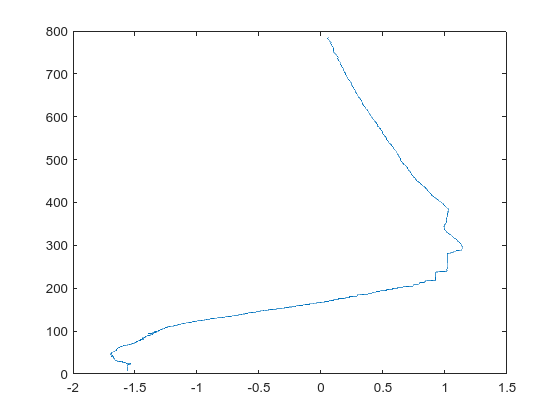

% Raw CTD data
plot(temp, depth)

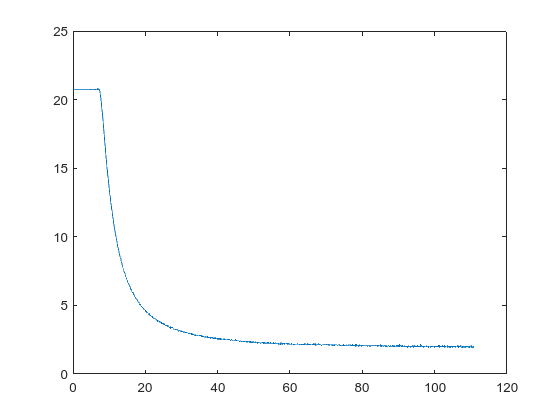

% Plot raw recorded data
plot(ts_s1,temp_s1)

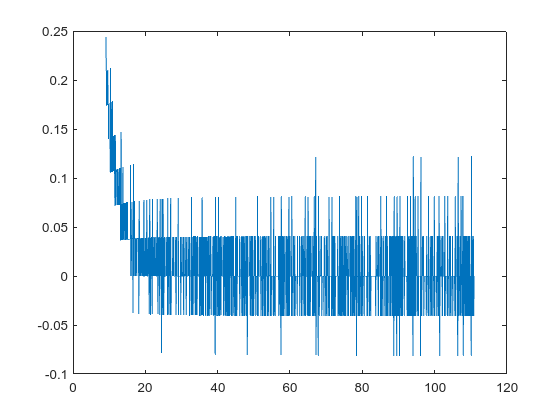

% Extract step response 
% Use raw impulse values to find "start"
raw_impulse_s1 = step2impulse(temp_s1,dt);
start_idx = find(raw_impulse_s1 == min(raw_impulse_s1));

% Crop data to step
cropped_s1 = temp_s1(start_idx:end);

% Rescale data based on step size
step_s1 = cropped_s1/(max(cropped_s1)-min(cropped_s1));
impulse_s1 = step2impulse(step_s1,dt);

% Make impulse function negative
% Since we used an ice bath, we put in a "negative" step
impulse_s1 = -impulse_s1;
plot(ts_s1(start_idx+1:end), impulse_s1)

% Create array of depths given speed and sampling interval (dt)
v1 = 0.25; % m/s
v2 = 1; % m/s

depths_v1 = 0:dt*v1:max(depth);
depths_v2 = 0:dt*v2:max(depth);

% Lookup temperature values at timestamps
temp_interp_v1 = interp1(depth, temp, depths_v1);
temp_interp_v2 = interp1(depth, temp, depths_v2);impulse_s1

impulse_s1 =     0.2436
    0.2090
    0.1743
    0.2093
    0.1746
    0.2097
    0.1749
    0.1401
    0.1753
    0.1755


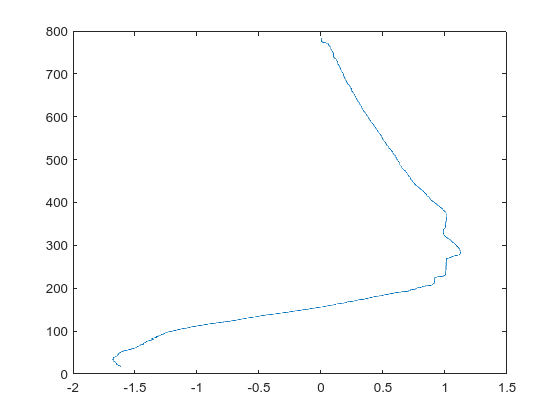

% Apply convolution to signal using impulse response
% Multiply by dt to account for "scale"
w = conv(temp_interp_v1, impulse_s1,'same')*dt;
plot(w, depths_v1)

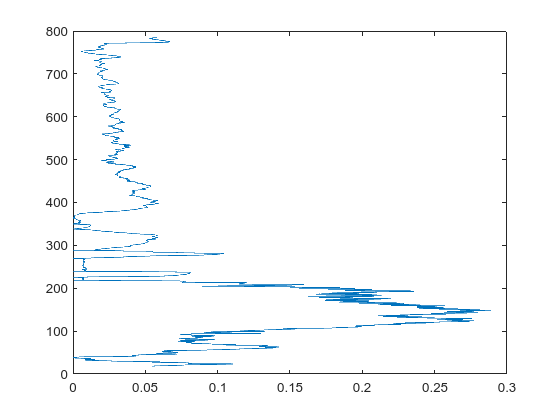

% Plot residuals
plot(abs(temp_interp_v1-w), depths_v1)